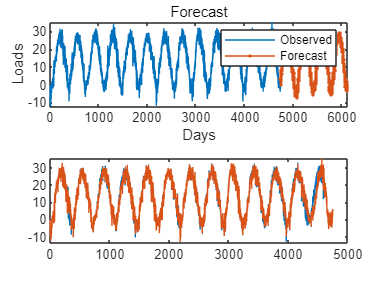

clc
clear all
load("matlab4.mat")
load("matlab5.mat")
T0 = 1000;
T = T0;
a = 0.3;
b = 0.1;
c = 1;
k = 10;
i = 0;
pos1 = 1;
pos2 = 1;
temp = 0;
index = 1;
Length = 100;
aaa = 0;
ppp = 0;
res = 0;
cnt = 1;
ppppp = 1 ;
TrainLimit = 4745;
key = 0;
limit1 = 0.5;
limit2 = 0.03;
xseries = 1:4745;
xseries2 = 1:1378;
u = 0;
for j = 1:4
    res(j) = 0;
end
for j = 1:4745
    y(j) = PekingTemp(j);
end
YReal = 0;
for j = 4746:6123
    YReal(j-4745) = PekingTemp(j);
end
% while true
    deltaT = k * T;
    while index + Length < TrainLimit
        i = i + 1;
        for j = 1:Length
            dy(j) = abs(y(index) - Fourier_8(index));
            s2(j) = dy(j) * dy(j);
            temp = temp + s2(j);
            index = index + 1;
        end
        u(i) = temp;
        temp = 0;
        if i < 4 || u(i) > res(i)
            P = exp(-u(i)/deltaT);
            re_P(cnt) = P;
            cnt = cnt + 1;
            seed = rand(1);
            if seed > P || i < 4
                forward1 = index - Length;
                for j = 1:Length
                    forward1 = forward1 + 1;
                    fy(forward1) = y(forward1);
                    key = key + 1;
                end
                if i > 4
                    num = c * (vvGM(u));
                    res(i+1) = num(i+1);
                else
                    res(i+1) = u(i);
                end
                continue;
            end
        end
        forward2 = index - Length + 1;
        for j = 1:Length
            ERR(j) = dy(j) / y(forward2);
            if ERR(j) > limit1
%                 testnum = a * (1 + b * abs(tanh(ERR(j) - limit1)));
%                 if testnum > 1
%                     testnum = 1;
%                 end
%             a = testnum;
            a = a * (1 + b * abs(tanh(ERR(j) - limit1)));
            elseif ERR(j) < limit2
                a = a * (1 - b * abs(tanh(ERR(j) - limit2)));
                if a < 0.01
                    a = 0.01;
                end
            end
            numOfA(ppppp) = a;
            ppppp = ppppp + 1;
            gamma(j) = a * dy(j);
            if gamma(j) > dy(j)
                gamma(j) = dy(j);
            end
            if y(forward2) > Fourier_8(forward2)
                fy(forward2) = y(forward2) - gamma(j);
            else 
                fy(forward2) = y(forward2) + gamma(j);
            end
            forward2= forward2 + 1;
        end
        num = c * (vvGM(u));
        res(i+1) = num(i+1);
    end
    if index < 4745
        for j = index : index + Length - 1
            fy(index) = y(index);
            index = index + 1;
            if index == 4746
                break
            end
        end
    end
    plot(xseries,y,xseries,fy)

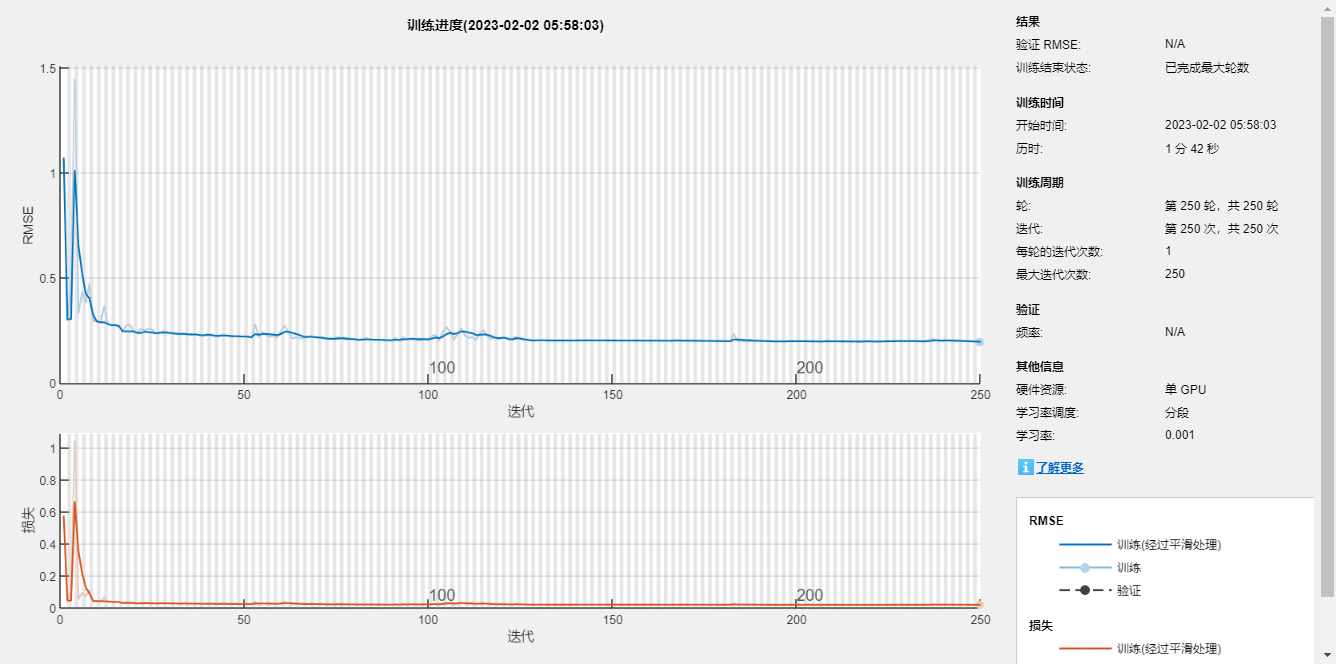


%     Y1 = fy;
%     data = Y1';
%     numTimeStepsTrain = floor(0.775*numel(data));
%     dataTrain = data(1:numTimeStepsTrain+1);
%     dataTest = data(numTimeStepsTrain+1:end);
%     mu = mean(dataTrain);
%     sig = std(dataTrain);
%     dataTrainStandardized = (dataTrain - mu) / sig;
%     XTrain = dataTrainStandardized(1:end-1);
%     YTrain = dataTrainStandardized(2:end);
%     numFeatures = 1;
%     numResponses = 1;
%     numHiddenUnits = 96*3;
%     layers = [ ...
%         sequenceInputLayer(numFeatures)
%         lstmLayer(numHiddenUnits)
%         fullyConnectedLayer(numResponses)
%         regressionLayer];
%     options = trainingOptions('adam', ...
%         'MaxEpochs',250, ...
%         'GradientThreshold',1, ...
%         'InitialLearnRate',0.005, ...
%         'LearnRateSchedule','piecewise', ...
%         'LearnRateDropPeriod',125, ...
%         'LearnRateDropFactor',0.2, ...
%         'Verbose',0, ...
%         'Plots','training-progress');
%     net = trainNetwork(XTrain,YTrain,layers,options);
%     dataTestStandardized = (dataTest - mu) / sig;
%     XTest = dataTestStandardized(1:end-1);
%     YTest = dataTest(2:end);
%     net = resetState(net);
%     net = predictAndUpdateState(net,XTrain);
%     YPred = [];
%     numTimeStepsTest = numel(XTest);
%     for i = 1:numTimeStepsTest
%         [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i),'ExecutionEnvironment','cpu');
%     end
%     YPred = sig*YPred + mu;
%     rmse = sqrt(mean((YPred-YTest).^2))
%     figure
%     subplot(2,1,1)
%     plot(YTest)
%     hold on
%     plot(YPred,'.-')
%     hold off
%     legend(["Observed" "Predicted"])
%     ylabel("Loads")
%     title("Forecast with Updates")
%     subplot(2,1,2)
%     stem(YPred - YTest)
%     xlabel("Days")
%     ylabel("Error")
%     title("RMSE = " + rmse)
%     figure
%     subplot(2,1,1)
%     plot(dataTrain(1:end-1))
%     hold on
%     idx = numTimeStepsTrain:(numTimeStepsTrain+numTimeStepsTest);
%     plot(idx,[data(numTimeStepsTrain) YPred],'.-')
%     hold off
%     xlabel("Days")
%     ylabel("Loads")
%     title("Forecast")
%     legend(["Observed" "Forecast"])
%     subplot(2,1,2)
%     plot(data)
%     xlabel("Days")
%     ylabel("Loads")
%     title("Daily load")
%     mae = mean(abs(YReal - YPred))
%     sse = sum((YPred - YReal).^2)
%     rmse = sqrt(mean((YPred-YReal).^2))
%     meap = mean(abs((YReal - YPred)./YReal))*100  
%     ans = rmse;
% 
%     plot(xseries2,YReal,xseries2,YPred)
%     if ans < RMSE
%         break
%     else
%         T = T - deltaT;
%     end 
% end

YReal = 0;
for i = 1:4745
    yyyy(i) = fy(i);
end
for i = 4746:6125
    yyyy(i) = PekingTemp(i);
end
for i = 4746:6123
    YReal(i-4745) = PekingTemp(i);
end
%序列的前 77.5% 用于训练，后 22.5% 用于测试
Y1 = yyyy;
data = Y1;
numTimeStepsTrain = floor(0.775*numel(data));
dataTrain = data(1:numTimeStepsTrain+1);
dataTest = data(numTimeStepsTrain+1:end);
 
%数据预处理，将训练数据标准化为具有零均值和单位方差。
mu = mean(dataTrain);
sig = std(dataTrain);
dataTrainStandardized = (dataTrain - mu) / sig;
 
%输入LSTM的时间序列交替一个时间步
XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);

%%
%创建LSTM回归网络，指定LSTM层的隐含单元个数96*3
%序列预测，因此，输入一维，输出一维
numFeatures = 1;
numResponses = 1;
numHiddenUnits = 96*3;
 
layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];
 
%指定训练选项，求解器设置为adam， 250 轮训练。
%梯度阈值设置为 1。指定初始学习率 0.005，在 125 轮训练后通过乘以因子 0.2 来降低学习率。
options = trainingOptions('adam', ...
    'MaxEpochs',250, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');
%训练LSTM
net = trainNetwork(XTrain,YTrain,layers,options);


dataTestStandardized = (dataTest - mu) / sig;
XTest = dataTestStandardized(1:end-1);
YTest = dataTest(2:end);

net = resetState(net);
net = predictAndUpdateState(net,XTrain);
 
YPred = [];
numTimeStepsTest = numel(XTest);
for i = 1:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i),'ExecutionEnvironment','cpu');
end
 
%使用先前计算的参数对预测去标准化。
YPred = sig*YPred + mu;
 
%计算均方根误差 (RMSE)。
rmse = sqrt(mean((YPred-YTest).^2))

rmse = 2.0147

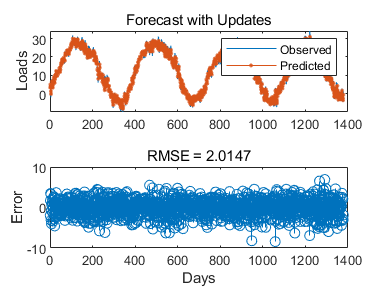


%将预测值与测试数据进行比较。
figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Predicted"])
ylabel("Loads")
title("Forecast with Updates")
 
subplot(2,1,2)
stem(YPred - YTest)
xlabel("Days")
ylabel("Error")
title("RMSE = " + rmse)

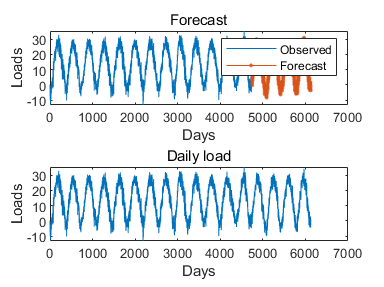

 
 
figure
subplot(2,1,1)
plot(dataTrain(1:end-1))
hold on
idx = numTimeStepsTrain:(numTimeStepsTrain+numTimeStepsTest);
plot(idx,[data(numTimeStepsTrain) YPred],'.-')
hold off
xlabel("Days")
ylabel("Loads")
title("Forecast")
legend(["Observed" "Forecast"])
subplot(2,1,2)
plot(data)
xlabel("Days")
ylabel("Loads")
title("Daily load")


mae = mean(abs(YReal - YPred))

mae = 1.5844

sse = sum((YPred - YReal).^2)

sse = 5.7039e+03

rmse = sqrt(mean((YPred-YReal).^2))

rmse = 2.0345

meap = mean(abs((YReal - YPred)./YReal))*100  

meap = 55.2227